# **表面等离激元的演示**

**        两介质界面上的表面等离激元（Surface Plasmon）模式具有特殊的场分布。瞬时表达式如下：**


$$\begin{array}{l}
E_1 =\frac{-k_1 }{\omega \varepsilon_{r1} }e^{-k_1 z} \sin (\omega t-\beta x)\\
E_2 =\frac{-k_2 }{\omega \varepsilon_{r2} }e^{k_2 z} \sin (\omega t-\beta x)
\end{array}$$


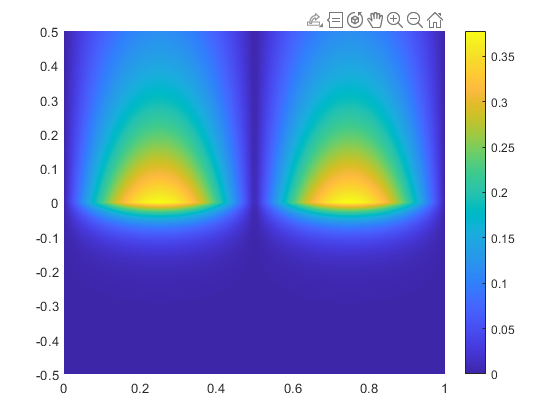

omega=2*pi; %设置角频率
c=3e8; %光速
k0=omega/c; 
epsilonr1=1; %介质1的相对介电常数;
epsilonr2=-8; %介质2的相对介电常数;
beta=k0*sqrt(epsilonr1*epsilonr2/(epsilonr1+epsilonr2));  %传播常数
k1=sqrt(-omega^2*epsilonr1*epsilonr1/(epsilonr1+epsilonr2));   %介质1的波矢量
k2=sqrt(-omega^2*epsilonr2*epsilonr2/(epsilonr1+epsilonr2));   %介质2的波矢量
t=linspace(0,1,100);
x=linspace(0,1,100);
z1=linspace(0,1,100);
z2=linspace(-1,0,100);
[X,Z1]=meshgrid(x,z1);
[~,Z2]=meshgrid(x,z2);
Ex1=-k1/(omega.*epsilonr1).*exp(-k1.*Z1).*sin(omega.*t-beta.*X);   %介质1中的电场强度
Ex2=-k2/(omega.*epsilonr2).*exp(k2.*Z2).*sin(omega.*t-beta.*X);    %介质2中的电场强度
Ex1=abs(Ex1);
Ex2=abs(Ex2);
figure
pcolor(X,Z1,Ex1);
hold on
pcolor(X,Z2,Ex2);
shading interp;
colorbar;
xlim([0.0 1.0])
ylim([-0.5 0.5])
set(gcf,'Visible','on');   	    %强制图片弹出显示